# Filtr Hilberta, modulacja AM

[x1, fs1] = audioread('mowa8000.wav'); x1 = x1'; x2 = fliplr(x1); 
fs = 400e3; 
fc1 = 100e3; fc2 = 110e3;
dA = .23;


% odp impulsowa ???
fc=100e3;         %czestotliwosc nosna
M=64; N=2*M+1; n=1:M;
h=(2/pi)*sin(pi*n/2).^2 ./n;    %połowa odpowiedzi impulsowej (TZ str. 352)
h=[-h(M:-1:1) 0 h(1:M)];        %cała odpowiedź dla n = ?M,...,0,...,M
w=blackman(N); w=w';            
hw=h.*w; 

Funkcje anonimowe:

t1 = length(x1)/fs1;
t = 0:1/fs:t1-1/fs;

DSB_C = @(x, t, fc) (1+x).*cos(2*pi*fc*t);
DSB_SC = @(x, t, fc) x.*cos(2*pi*fc*t);
SSB_SC = @(x, t, fc, s) .5*x.* cos(2*pi*fc*t) + sign(s)*.5*x.*sin(2*pi*fc*t); % ????

Nadprobkowanie sygnalow

xr1 = resample(x1, fs, fs1);
xr2 = resample(x2, fs, fs1);

Modulacja

yDSBC_1 = DSB_C(xr1, t, fc1)*dA;
yDSBC_2 = DSB_C(xr2, t, fc1)*dA;

yDSBSC_1 = DSB_SC(xr1, t, fc1)*dA;
yDSBSC_2 = DSB_SC(xr2, t, fc1)*dA;

ySSBSC_1pos = SSB_SC(xr1, t, fc1, 1)*dA;
ySSBSC_1neg = SSB_SC(xr1, t, fc1, -1)*dA;

ySSBSC_2pos = SSB_SC(xr2, t, fc1, 1)*dA;
ySSBSC_2neg = SSB_SC(xr2, t, fc1, -1)*dA;

xm1 = [yDSBC_1; yDSBSC_1; ySSBSC_1pos; ySSBSC_1neg];
xm2 = [yDSBC_2; yDSBSC_2; ySSBSC_2pos; ySSBSC_2neg];
xm1Legend = ["yDSBC_1", "yDSBSC_1", "ySSBSC_1pos", "ySSBSC_1neg"];
xm2Legend = ["yDSBC_2", "yDSBSC_2", "ySSBSC_2pos", "ySSBSC_2neg"];

Wykresy

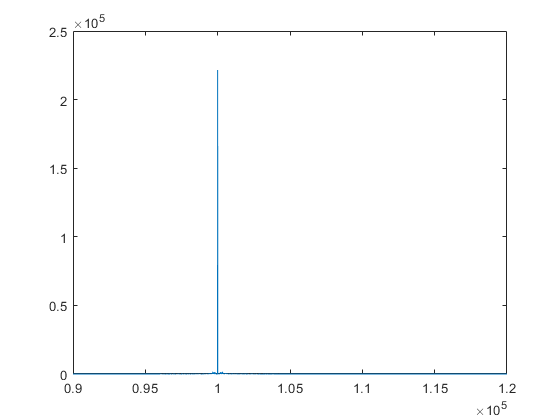

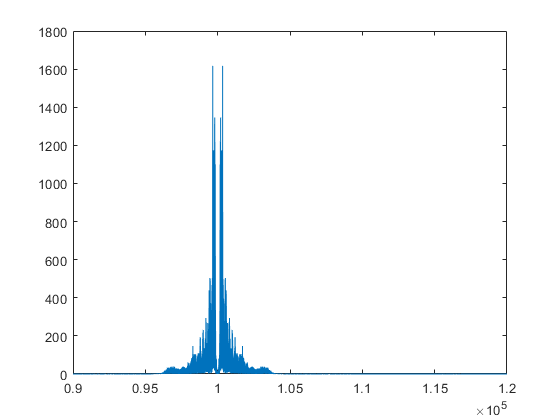

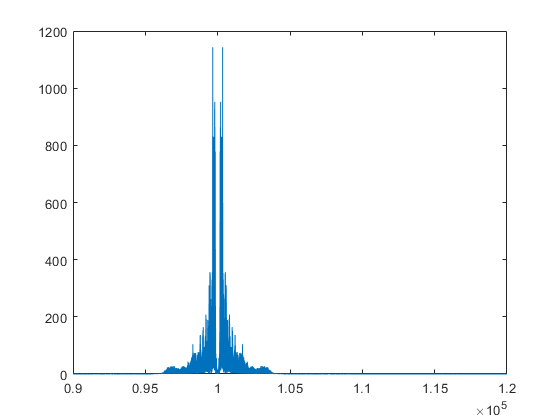

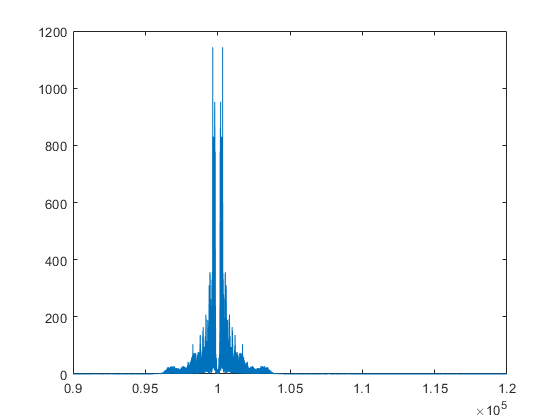

for i=1:size(xm1, 1)
    tmpXM = fft(xm1(i, :));
    figure
    plot((0:length(tmpXM)-1)/length(tmpXM)*fs, abs(tmpXM));
    xlim([90e3 120e3]);
end

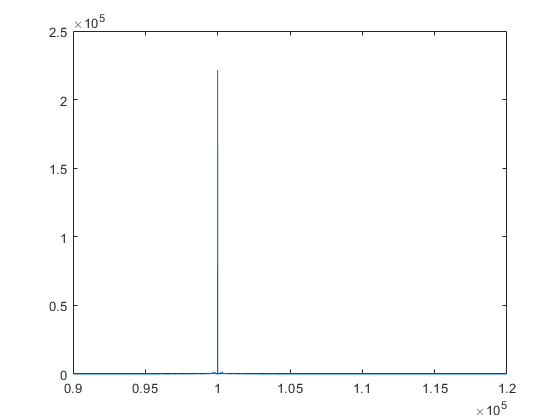

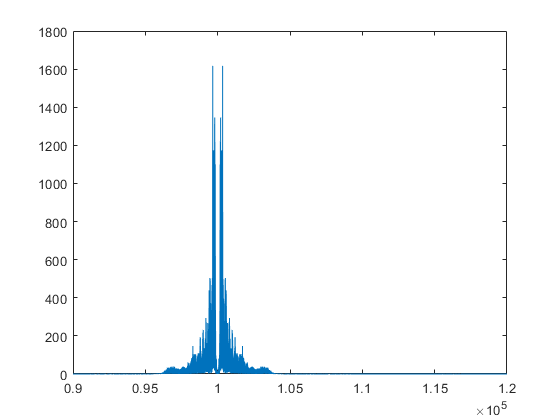

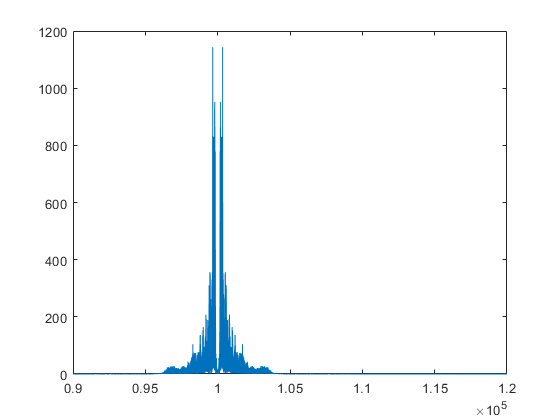

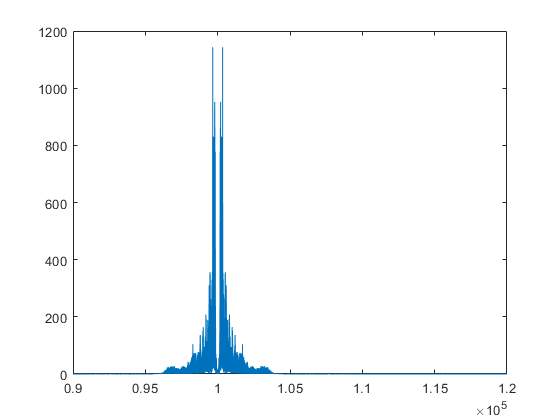


for i=1:size(xm2, 1)
    tmpXM = fft(xm2(i, :));
    figure
    plot((0:length(tmpXM)-1)/length(tmpXM)*fs, abs(tmpXM));
    xlim([90e3 120e3]);
end